# Second approach

## Given enviroment

Given the table with the patient in an arbitrary pose

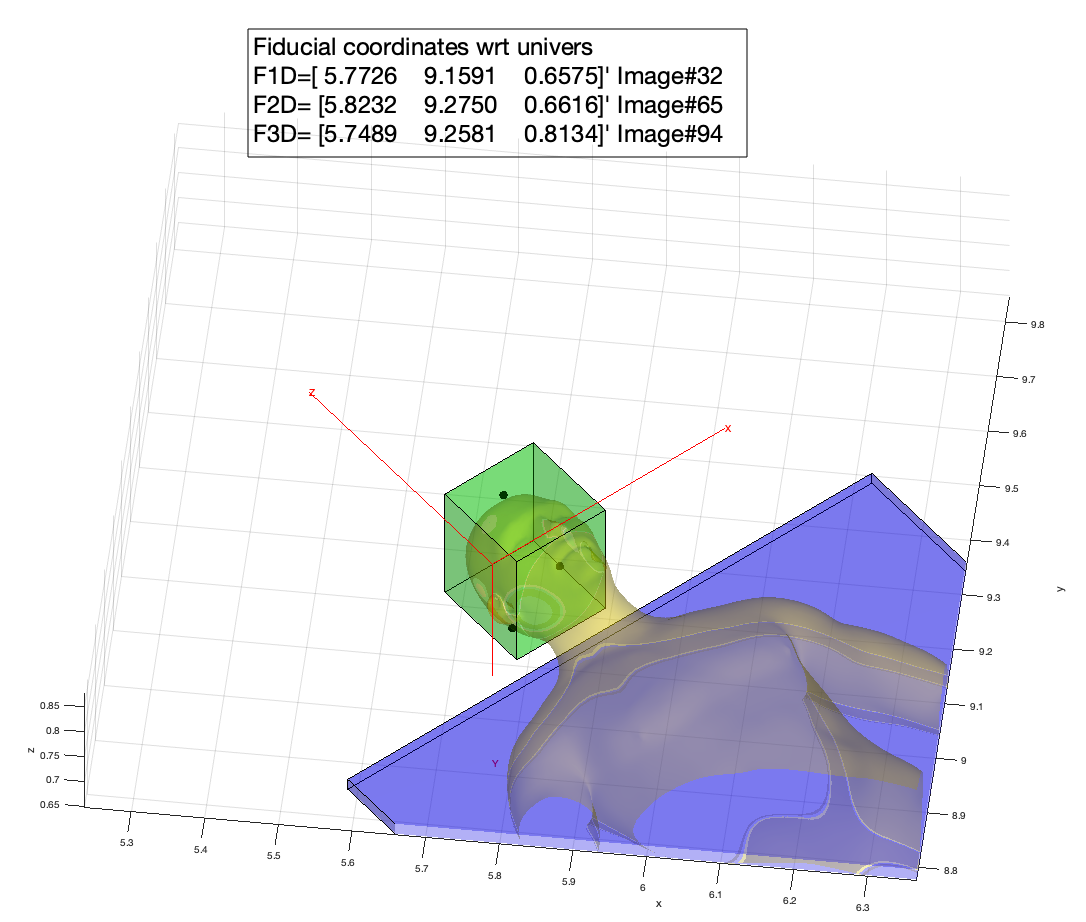

Open the given figure

Double click on it or select and right click/evaluate

clear
open('3_Second_approach_Patient_pose.fig')
hold on

## Robot Frame wrt {U}

The Robot Rosa is located near by the patient 

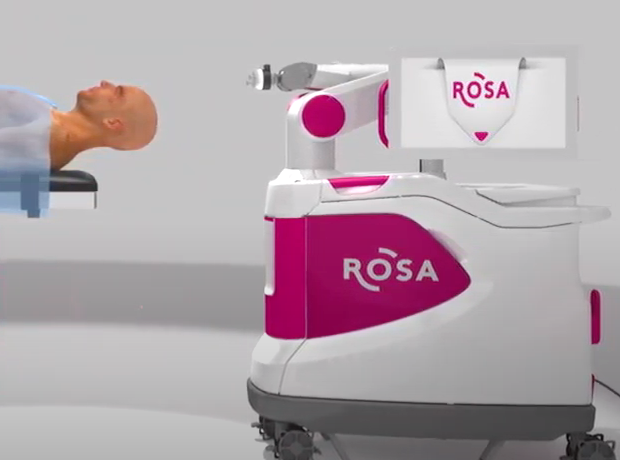

Locating the Robot

mdl_puma560;
p560.base=transl(5.75,9.75,0)*trotz(-pi/4)

 
p560 = 
 
Puma 560 [Unimation]:: 6 axis, RRRRRR, stdDH, fastRNE            
 - viscous friction; params of 8/95;                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|     0.4318|          0|          0|
|  3|         q3|    0.15005|     0.0203|    -1.5708|          0|
|  4|         q4|     0.4318|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
base:    t = (5.75, 9.75, 0), RPY/xyz = (-45, 0, 0) deg          
 


p560.plot(qr,'zoom',1.5)
axis([5 6.5 8.8 10 0 1.8])
T_R_U=p560.base.T

T_R_U =     0.7071    0.7071         0    5.7500
   -0.7071    0.7071         0    9.7500
         0         0    1.0000         0
         0         0         0    1.0000


## Fiducial wrt {U}

To emulate the action of measuring the fiducial wrt Robot Frame I gave you the fiducials coordinate wrt {U}.

F123=open ('Fiducial_U.mat');
F1= F123.F1;
F2= F123.F2;
F3= F123.F3;
F1

F1 =     5.7726
    9.1591
    0.6575


F2

F2 =     5.8232
    9.2750
    0.6616


F3

F3 =     5.7489
    9.2581
    0.8134


## Transform compound

We will need the following Reference Frames: {U}, {R}, {F}, {I} 

and the Following Transformation: $ {}_R^U{T,{}_F^R{T,{}_I^F{Tand{}_I^R{T$

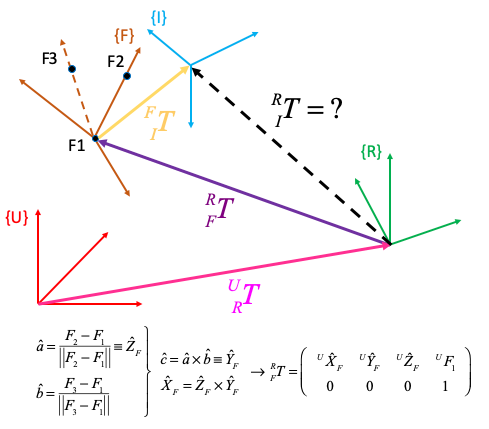

It is clear that we will need the transformation Image to Robot, i.e. ${}_I^R{T$ to correctly make the tumor surgery.

Remeber the doctor, based on the Dicom image locate the Tumor (i.e Reference Image {I}) .

## T_F_R Frame Description

**Pay attention:** and touch the fiducial to locate them wrt its own Reference Frame {R}.

You need to place the Robot Puma in RF {U} and infer the Fiducial locations wrt {R}

### Fiducial in RF Robot {R}

Notice: You have fiducial in RF {U}={A } and you want it in RF{R}={B} ... So  ${}^BP = {}_B^A{T^{ - 1}}{}^AP$

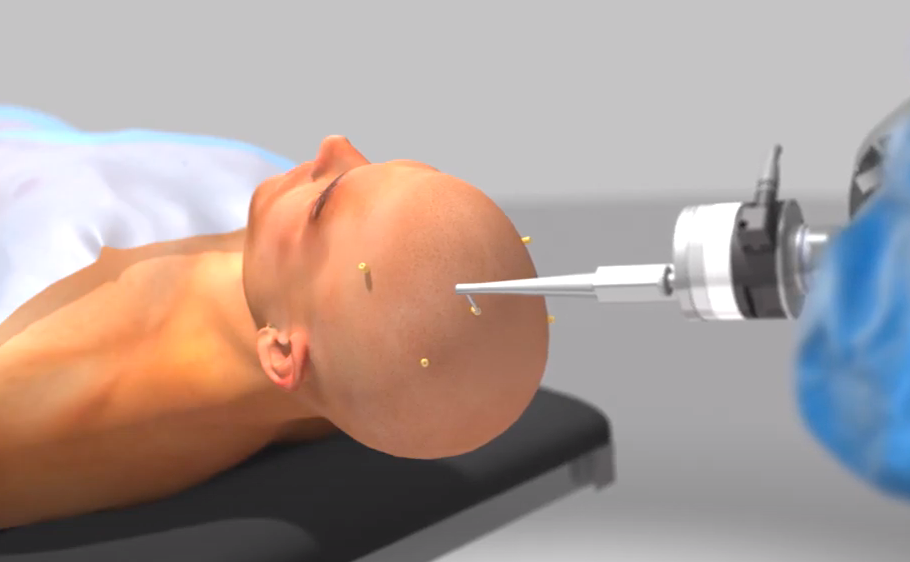

Fi_R=inv(T_R_U)*[F1 F2 F3;ones(1,3)]

Fi_R =     0.4338    0.3876    0.3470
   -0.4018   -0.2841   -0.3486
    0.6575    0.6616    0.8134
    1.0000    1.0000    1.0000


### RF Fiducial {F} wrt RF {R}

It is needed to use an auxiliary Reference Frame formed by the three fiducials becouse they are measured by the Robot using the teach Tool (See above section) and the Computed Tomography (Dicom images).

We will use the fiducials in RF {R}

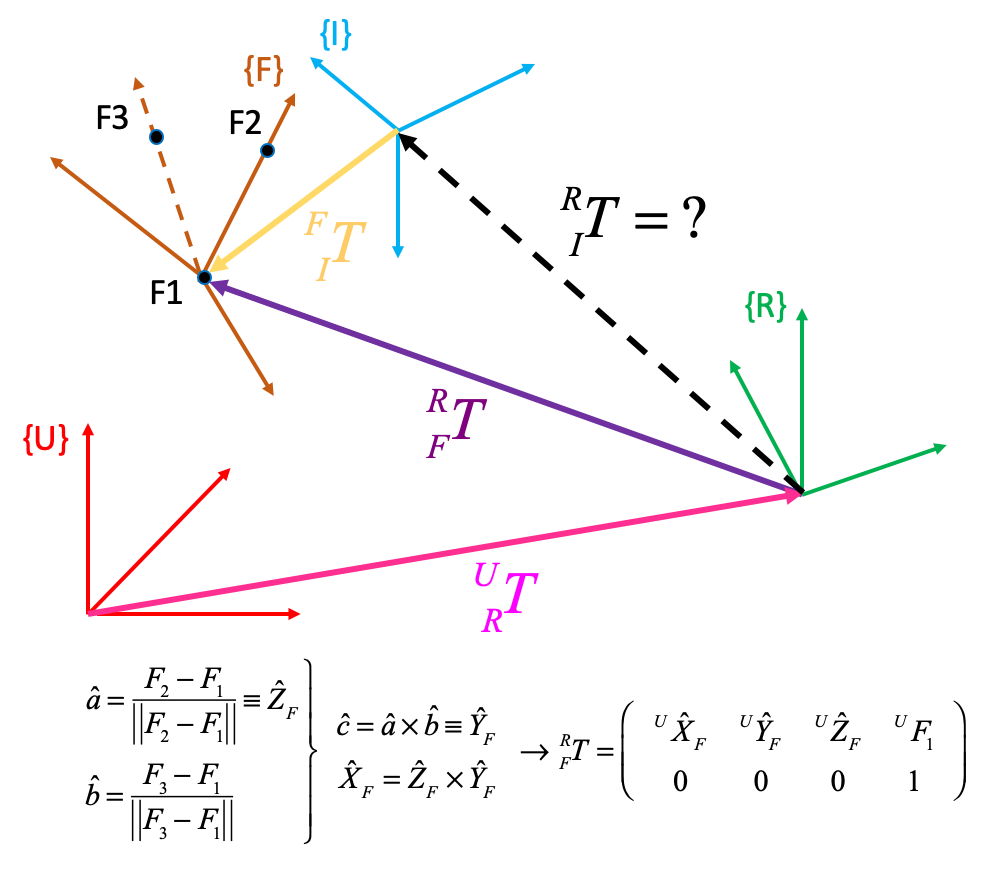

#### Orientation wrt {R}

Yf = (Fi_R(1:3,2)-Fi_R(1:3,1))/norm(Fi_R(1:3,2)-Fi_R(1:3,1));
b=(Fi_R(1:3,3)-Fi_R(1:3,1))/norm(Fi_R(1:3,3)-Fi_R(1:3,1));
Zf = cross(Yf,b)/norm(cross(Yf,b));
Xf = cross(Yf,Zf)/norm(cross(Yf,Zf));

#### Frame Description  

${}_F^R{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{R}

T_F_R = [[Xf;0] [Yf;0] [Zf;0] [Fi_R(:,1)]]

T_F_R =     0.3353   -0.3652    0.8684    0.4338
    0.1638    0.9304    0.3280   -0.4018
   -0.9278    0.0323    0.3718    0.6575
         0         0         0    1.0000


## RF Fiducial {F} wrt RF {U}

The answer to this question is ${}_F^U{T={}_R^U{T{}_F^R{T$

T_F_U=T_R_U*T_F_R

T_F_U =     0.3529    0.3996    0.8460    5.7726
   -0.1213    0.9161   -0.3822    9.1591
   -0.9278    0.0323    0.3718    0.6575
         0         0         0    1.0000


trplot(T_F_U,'Frame','F','color', 'b','length',0.4)

### Check T_F_U 

Going from {U} to {F}

Notice that the origen ${}^U{P_{F1ORG}}$is coincident with the coordinate of fiducial 1 F1 in RF {U}

RPY=tr2rpy(T_F_R,'zyx')

RPY =     0.0865    1.1884    0.4544


T_F1_U=T_R_U*transl(Fi_R(1:3,1))*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1))

T_F1_U =     0.3529    0.3996    0.8460    5.7726
   -0.1213    0.9161   -0.3822    9.1591
   -0.9278    0.0323    0.3718    0.6575
         0         0         0    1.0000


T_F_U

T_F_U =     0.3529    0.3996    0.8460    5.7726
   -0.1213    0.9161   -0.3822    9.1591
   -0.9278    0.0323    0.3718    0.6575
         0         0         0    1.0000


## Fiducials wrt {I} 

From Dicom Images

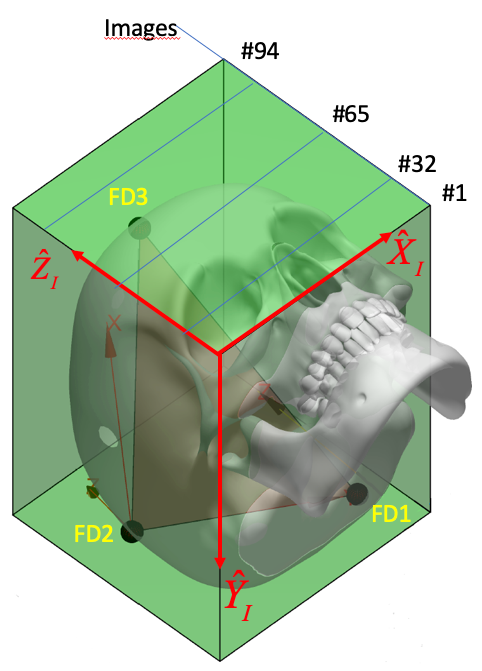

Taking data from Dicom images

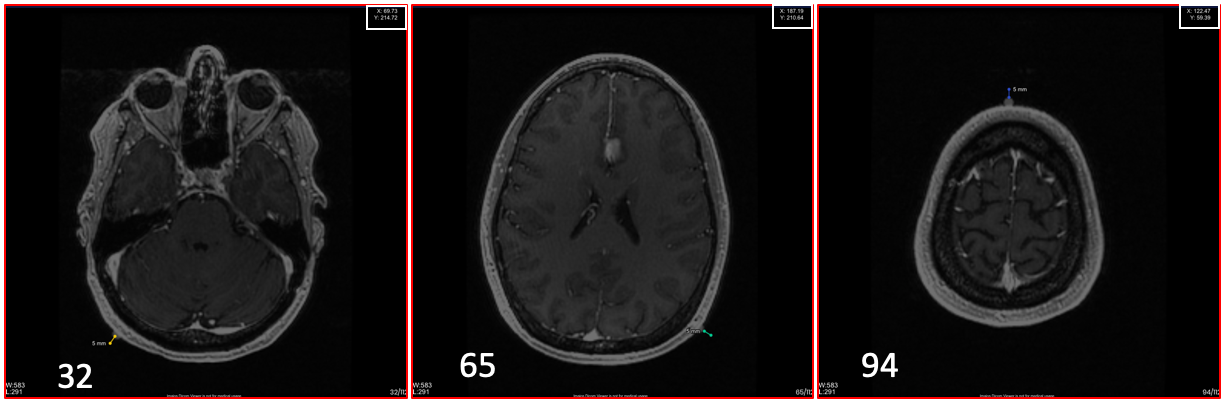

pitch =1.4; % Pitch among slices 
F1D = [0.06973 0.21496 0.032*pitch]'; %image #32
F2D = [0.18743 0.21088 0.065*pitch]'; %image #65
F3D = [0.12295 0.05915 0.094*pitch]'; %image #94
Tumor=[0.13400 0.09600 0.078*pitch]';%image #78

## Visualizing fiducials and tumor

### Image Frame 

Plotting Image Reference Frame at origen of Reference Frame Univers {U}

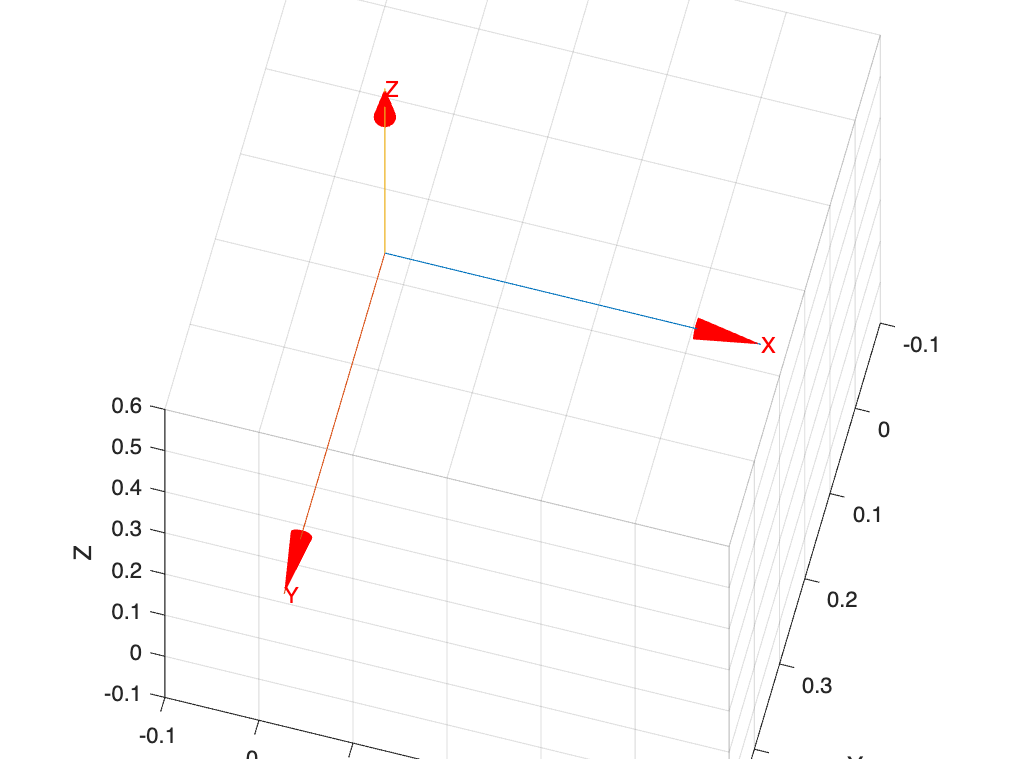

figure
trplot(eye(3),'Frame','I','color', 'r','length',0.4, 'arrow','width',0.4)
hold on
axis([-0.1 0.5 -0.1 0.5 -0.1 0.6])
view (-15,-65) % For better understanding

### Fiducials and tumor in {I} 

We use a sphere to represent a fiducial

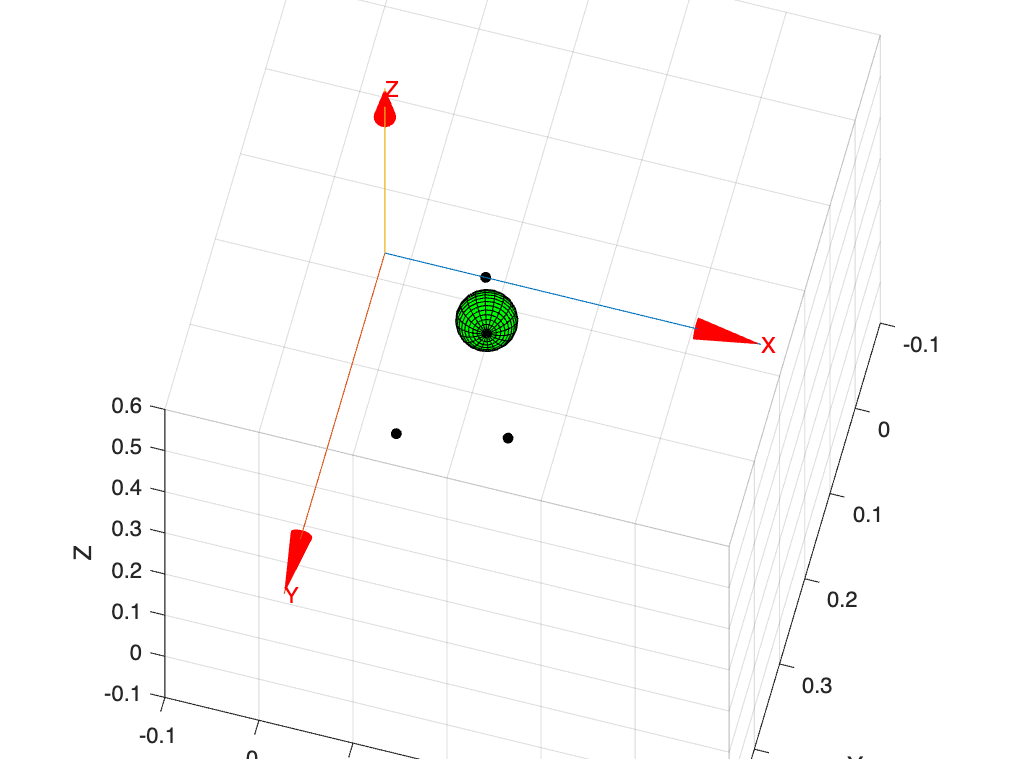

[X,Y,Z] = sphere;
r = 0.005; % radius of the sphere
X2 = X * r;
Y2 = Y * r;
Z2 = Z * r; 
surf(X2+F1D(1),Y2+F1D(2),Z2+F1D(3),'FaceColor',[0 1 0])
surf(X2+F2D(1),Y2+F2D(2),Z2+F2D(3),'FaceColor',[0 1 0])
surf(X2+F3D(1),Y2+F3D(2),Z2+F3D(3),'FaceColor',[0 1 0])
surf(X*0.032+Tumor(1),Y*0.032+Tumor(2),Z*0.032+Tumor(3),'FaceColor',[0 1 0])

## T_F_I - Frame Description 

As we mention before It is needed to use the Fiducial as auxiliary Reference Frame 

Extracted from the triangle F1D - F2D - F3D

Same procedure as before

### Orientation 

YfD = (F2D-F1D)/norm(F2D-F1D);
bD = (F3D-F1D)/norm(F3D-F1D);
ZfD = cross(YfD,bD)/norm(cross(YfD,bD));
XfD = cross(YfD,ZfD)/norm(cross(YfD,ZfD));

### Frame Description  

${}_F^I{T$ take the Fiducial 1 as ${}^A{P_{BORG}}$ in our case A is RF{I}

T_F_I = [[XfD;0] [YfD;0] [ZfD;0] [F1D;1]]

T_F_I =     0.1638    0.9304    0.3280    0.0697
    0.9278   -0.0323   -0.3718    0.2150
   -0.3353    0.3652   -0.8684    0.0448
         0         0         0    1.0000


det(T_F_I)

ans = 1.0000

### Visualizing T_F_I

Fiducial Reference Frame wrt Reference frame {I} at origen of {U}

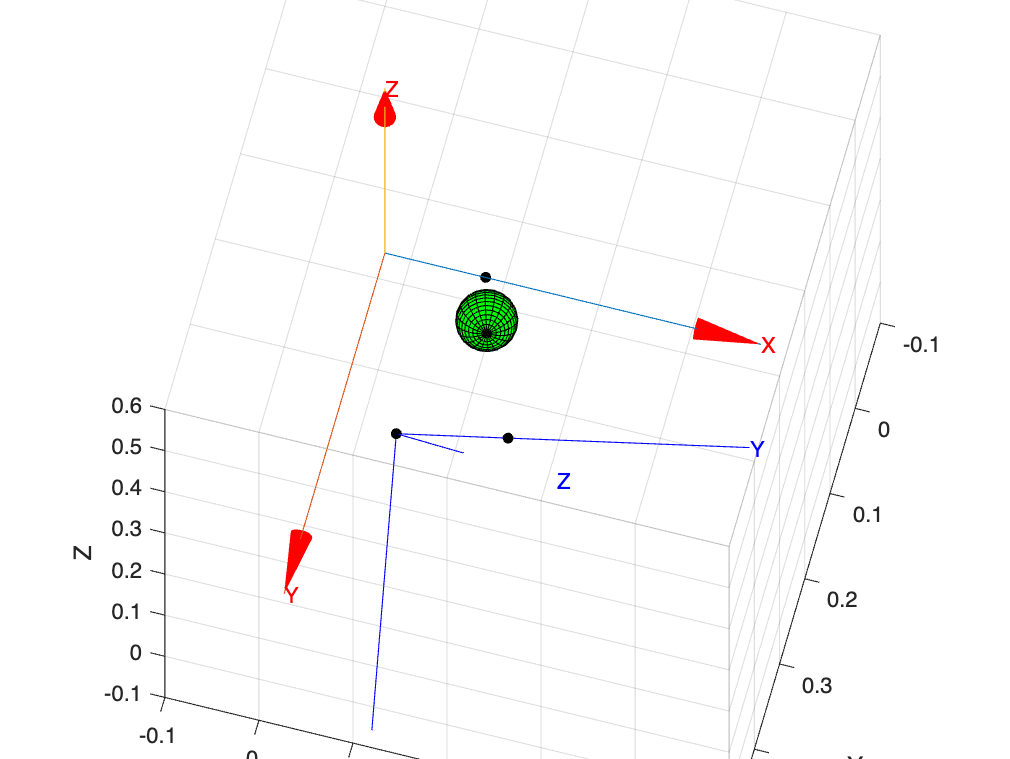

trplot(T_F_I,'Frame','F','color', 'b','length',0.4)

Check T_F_I as Going from {I} to {F}

RPY=tr2rpy(T_F_I,'zyx')

RPY =     2.7435    0.3419    1.3961


T_F_U2=transl(F1D)*trotz(RPY(3))*troty(RPY(2))*trotx(RPY(1))

T_F_U2 =     0.1638    0.9304    0.3280    0.0697
    0.9278   -0.0323   -0.3718    0.2150
   -0.3353    0.3652   -0.8684    0.0448
         0         0         0    1.0000


T_F_I

T_F_I =     0.1638    0.9304    0.3280    0.0697
    0.9278   -0.0323   -0.3718    0.2150
   -0.3353    0.3652   -0.8684    0.0448
         0         0         0    1.0000


## RF Image {I} wrt RF {U}

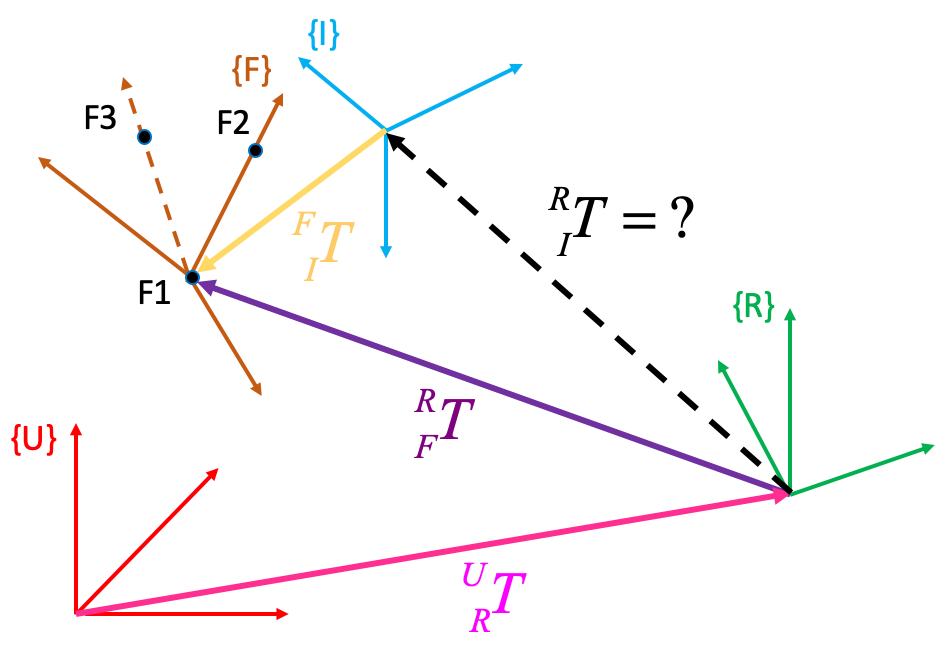

We have the Reference Frame {F} wrt {U} ${}_F^U{T={}_R^U{T{}_F^R{T$ and also ${}_F^I{T $, so ... ${}_I^U{T={}_F^U{T{}_F^I{T^{-1}$

T_I_U=T_F_U*inv(T_F_I)

T_I_U =     0.7071    0.0000   -0.7071    5.7550
    0.7071   -0.0000    0.7071    9.0781
    0.0000   -1.0000   -0.0000    0.8725
         0         0         0    1.0000


Ckeck that ${}_I^U{T$ is coincident with the given Image Reference Frame 

trplot(T_I_U,'Frame','I','color', 'cyan','length',0.7)

## T_I_R System equation


$$ {}_I^U{T={}_F^U{T{}_F^I{T^{-1}={}_R^U{T{}_I^R{T\\
{}_I^R{T={}_R^U{T^{-1}{}_F^U{T{}_F^I{T^{-1}$$


T_I_R=inv(T_R_U)*T_F_U*inv(T_F_I)

T_I_R =     0.0000    0.0000   -1.0000    0.4786
    1.0000    0.0000    0.0000   -0.4716
    0.0000   -1.0000   -0.0000    0.8725
         0         0         0    1.0000


## Overall ckecking

### Fiducials in Robot Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Robot Reference Frame

Fi_R2=T_I_R*[[F1D F2D F3D];ones(1,3)]

Fi_R2 =     0.4338    0.3876    0.3470
   -0.4018   -0.2841   -0.3486
    0.6575    0.6616    0.8134
    1.0000    1.0000    1.0000


Fi_R

Fi_R =     0.4338    0.3876    0.3470
   -0.4018   -0.2841   -0.3486
    0.6575    0.6616    0.8134
    1.0000    1.0000    1.0000


### Fiducials in Univers Frame

As a matter of proof, ckeck that given Fiducials coordinates in Image Reference Frame we can obtain them in Univers Reference Frame.

Fi_R2=T_R_U*T_I_R*[[F1D F2D F3D];ones(1,3)]

Fi_R2 =     5.7726    5.8232    5.7489
    9.1591    9.2750    9.2581
    0.6575    0.6616    0.8134
    1.0000    1.0000    1.0000
